% Cargar datos
DATA = xlsread('Five_times_Kinematics_HT_Query_final.xlsx');

MF = DATA(:,2);
X = DATA(:,5:end)';
[n, p] = size(X');
fprintf('El dataset sin outliers tiene %d muestras y %d dimensiones.\n', n, p);

El dataset sin outliers tiene 46 muestras y 77 dimensiones.


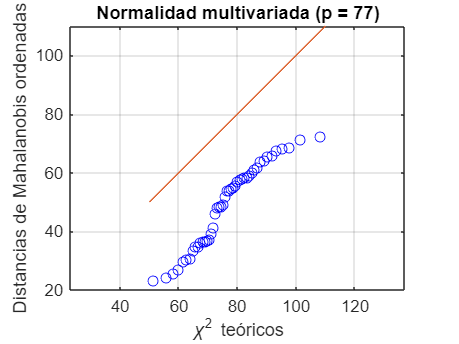

mu = mean(X);             % 1 x p
S = cov(X);               % p x p
invS = inv(S); %pinv

% Calcular distancias de Mahalanobis
D2 = zeros(n, 1);
for i = 1:n
    diff = X(i, :) - mu;
    D2(i) = diff * invS * diff';
end

% Cuantiles teóricos de chi-cuadrado con p grados de libertad
chi2_quant = chi2inv(((1:n)' - 0.5) / n, p);
D2_sorted = sort(D2);

% Graficar el Chi-square plot
figure;
plot(chi2_quant, D2_sorted, 'bo');
hold on;
refline(1, 0);  % línea identidad
xlabel('\chi^2 teóricos');
ylabel('Distancias de Mahalanobis ordenadas');
title(['Normalidad multivariada (p = ', num2str(p), ')']);
axis equal;
grid on;

bivariate normality

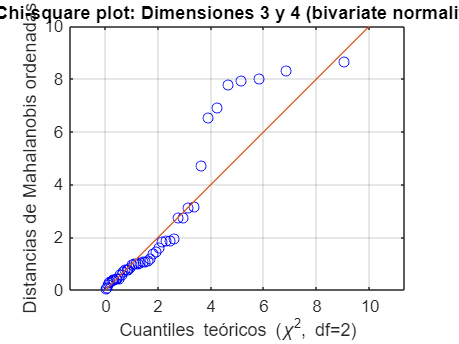

% Seleccionar dim 3 y 4
X_sub = X(:, [3 4]);  % n x 2

% Calcular vector de medias y matriz de covarianza
mean_vec = mean(X_sub);          % 1 x 2
cov_mat = cov(X_sub);            % 2 x 2
inv_cov = pinv(cov_mat);

% Calcular distancias de Mahalanobis
mahal_dist = zeros(n, 1);
for i = 1:n
    diff = X_sub(i, :) - mean_vec;
    mahal_dist(i) = diff * inv_cov * diff';
end

% Cuantiles teóricos de chi-cuadrado con 2 grados de libertad
chi2_q = chi2inv(((1:n)' - 0.5) / n, 2);  % para bivariado, df = 2

% Graficar Chi-square plot
figure;
plot(chi2_q, sort(mahal_dist), 'bo');
hold on;
refline(1, 0);  % línea identidad
xlabel('Cuantiles teóricos (\chi^2, df=2)');
ylabel('Distancias de Mahalanobis ordenadas');
title('Chi-square plot: Dimensiones 3 y 4 (bivariate normality)');
axis equal;
grid on;

ejemplo de boostrap multivariate normality

DATA = xlsread('Five_times_Kinematics_HT_Query_final.xlsx');

MF = DATA(:,2);
X = DATA(:,5:end)';
[n, p] = size(X');
fprintf('El dataset sin outliers tiene %d muestras y %d dimensiones.\n', n, p);

El dataset sin outliers tiene 46 muestras y 77 dimensiones.


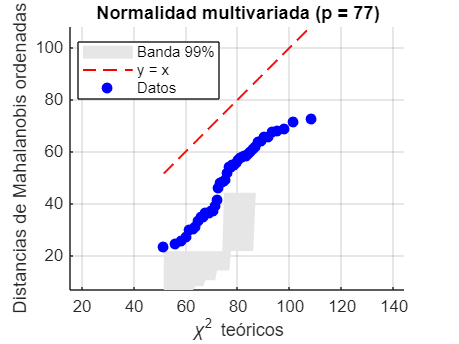

mu = mean(X);             % 1 x p
S = cov(X);               % p x p
invS = inv(S);
% Calcular distancias de Mahalanobis observadas
D2 = zeros(n, 1);
for i = 1:n
    diff = X(i, :) - mu;
    D2(i) = diff * invS * diff';
end
D2_sorted = sort(D2);

% Cuantiles teóricos de chi-cuadrado con p grados de libertad
chi2_quant = chi2inv(((1:n)' - 0.5) / n, p);

% -----------------------------
% Bootstrap no paramétrico
% -----------------------------
B = 500;
alpha = 0.01;
lower_p = alpha/2;
upper_p = 1 - alpha/2;

D2_boot = zeros(n, B);
for b = 1:B
    idx = randi(n, n, 1);       % re-muestreo con reemplazo
    Xb = X(idx, :);

    mub = mean(Xb);
    Sb = cov(Xb);
    invSb = pinv(Sb);

    D2b = zeros(n,1);
    for i = 1:n
        diff_b = Xb(i,:) - mub;
        D2b(i) = diff_b * invSb * diff_b';
    end
    D2_boot(:,b) = sort(D2b);
end

% Calcular bandas de confianza
lower_env = quantile(D2_boot, lower_p, 2);
upper_env = quantile(D2_boot, upper_p, 2);

% -----------------------------
% Gráfico Chi-square plot
% -----------------------------
figure;
hold on;
fill([chi2_quant; flipud(chi2_quant)], ...
     [lower_env; flipud(upper_env)], ...
     [0.9 0.9 0.9], 'EdgeColor', 'none');
plot(chi2_quant, chi2_quant, 'r--', 'LineWidth', 1.2); % identidad
plot(chi2_quant, D2_sorted, 'bo', 'MarkerFaceColor','b');

xlabel('\chi^2 teóricos');
ylabel('Distancias de Mahalanobis ordenadas');
title(['Normalidad multivariada (p = ', num2str(p), ')']);
legend('Banda 99%', 'y = x', 'Datos', 'Location', 'best');
axis equal;
grid on;